%Tomasz Indeka
%MNUM-Projekt
%zadanie 1.20, pkt 2
%WRozwiązywanie równań metodą Choleskiego - Banachowicza

%n-wielkość macierzy pierwotnej
%A-macierz rownań liniowych
%b-rozwiązanie rownania Ax=b
%x-wektor rozwiązań macierzy A
%m-mnożnik wielkości macierzy pierwornej
%r-rożnica między wynikiem obliczonym, a prawidłowym
%res-norma z rożnicy r

## a)

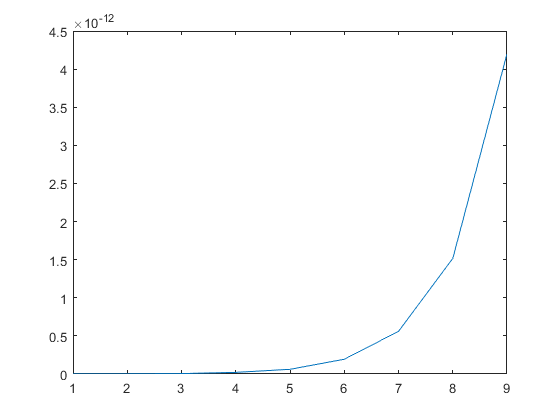

m=1;
while m<=9 % warunek na wielkośc macierzy zależny od posiadanego sprzętu i czasu
n = 10*2^(m-1);
A = zeros(n);
i=1;
while i<=n %obliczanie macierzy A za pomocą podanego w treści zadania wzoru
    j=1;
    while j<=n
        if j==i
            A(j,i)=10;
        elseif i==(j+1) || i==(j-1)
            A(j,i)=2.5;
        end
        j=j+1;
    end
    i=i+1;
end

b = zeros(n,1); 
i=1;
while i<=n %obliczanie wektora b za pomocą podanego w treści zadania wzoru
    b(i,1)=4-(i/2);
    i=i+1;
end

x = Choleski(n,A,b); % wywolanie funkcji obliczającej x
r=A*x-b;
res(m) = residuum(n,r); % wywolanie funkcji obliczającej residuum
m=m+1;
end
plot(res)

## b)

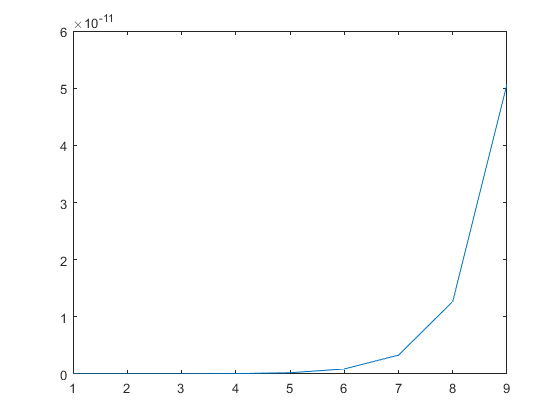

m=1;
while m<=9 % warunek na wielkośc macierzy zależny od posiadanego sprzętu i czasu
n = 10*2^(m-1);
A = zeros(n);
i=1;
while i<=n %obliczanie macierzy A za pomocą podanego w treści zadania wzoru
    j=1;
    while j<=n
        if j==i
            A(j,i)=3*n*n-i;
        else
            A(j,i)=i+j+1;
        end
        j=j+1;
    end
    i=i+1;
end

b = zeros(n,1);
i=1;
while i<=n %obliczanie wektora b za pomocą podanego w treści zadania wzoru
    b(i,1)=2.5+0.6*i;
    i=i+1;
end

x=Choleski(n,A,b); % wywolanie funkcji obliczającej x
r=A*x-b;
res(m) = residuum(n,r); % wywolanie funkcji obliczającej residuum
m=m+1;
end
plot(res)

## c)

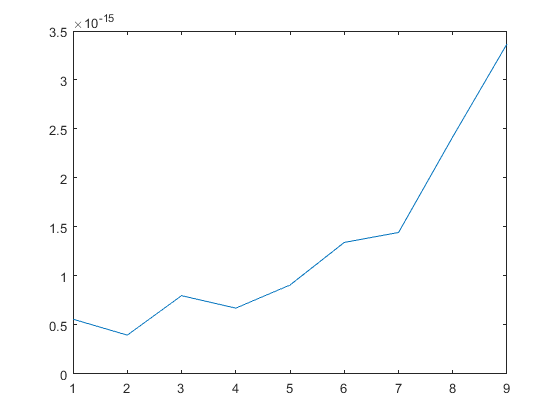

m=1;
while m<=9 % warunek na wielkośc macierzy zależny od posiadanego sprzętu i czasu
n = 10*2^(m-1);
A = zeros(n);
i=1;
while i<=n %obliczanie macierzy A za pomocą podanego w treści zadania wzoru
    j=1;
    while j<=n
        if j==i
            A(j,i)=0.1*n+0.3*i;
        else
            A(j,i)=1/(6*(i+j+1));
        end
        j=j+1;
    end
    i=i+1;
end

b = zeros(n,1);
i=1;
while i<=n %obliczanie wektora b za pomocą podanego w treści zadania wzoru
    b(i,1)=5/(3*i);
    i=i+1;
end

x=Choleski(n,A,b); % wywolanie funkcji obliczającej x
r=A*x-b;
res(m) = residuum(n,r); % wywolanie funkcji obliczającej residuum
m=m+1;
end
plot(res)